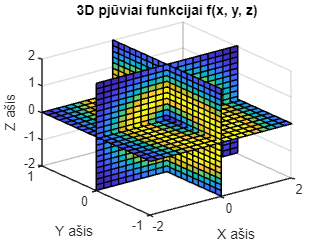

x = linspace(-2, 2, 20);
y = linspace(-2, 2, 20);
z = linspace(-1, 1, 20);
[X, Y, Z] = meshgrid(x, y, z);

F = sin((X.^2 + Y.^2 + Z.^2) / 20) .* exp(-(X.^2 + Y.^2 + Z.^2));

figure
h = slice(X, Y, Z, F, 0, 0, 0);
rotate(h, [1 0 0], 90);
rotate(h, [0 1 0], 90);
xlabel('X ašis')
ylabel('Y ašis')
zlabel('Z ašis')
title('3D pjūviai funkcijai f(x, y, z)')
grid on

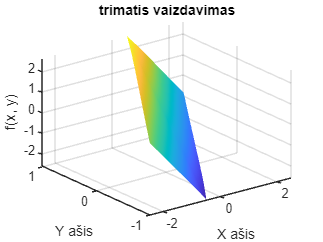

x = linspace(-2, 2, 50); 
y = linspace(-2, 2, 50);
[X, Y] = meshgrid(x, y); 

F = sin(abs(X + Y) / 20) .* exp(-abs(X + Y));

figure
h = surf(X, Y, F, 'FaceColor', 'green', 'EdgeColor', 'none');
shading interp
xlabel('X ašis')
ylabel('Y ašis')
zlabel('f(x, y)')
title('trimatis vaizdavimas')
rotate(h, [1 0 0], 60);
rotate(h, [0 1 0], 60);
grid on

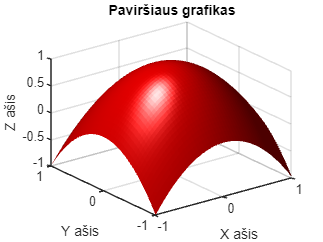

x = linspace(-1, 1, 50);
y = linspace(-1, 1, 50);
[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

figure
surf(X, Y, Z, 'FaceColor', 'r', 'EdgeColor', 'none')
xlabel('X ašis')
ylabel('Y ašis')
zlabel('Z ašis')
title('Paviršiaus grafikas')
grid on

camlight left